# Updated Slope Figure and analysis for SFN poster

i used this to get the figures of the slope analysis for the sfn poster.

cool this is that all plots and analysis (and tables) are condences into a single figure.

# Get Master Data Set

%Generate Master Data Set
% First retreive Master Data Set
clear 
close all force
cog_task_list = {'PVT', 'GoNogo', 'Math'};
cog_task_list = {'PVT'};

DF = dfmaster(cogtestlist=cog_task_list);


Getting GPSD during PVT Task. . . . . . . . . . . . -done

Getting Network Props during PVT: . . . . . . . . . . . . -done


### Select variables to analyze

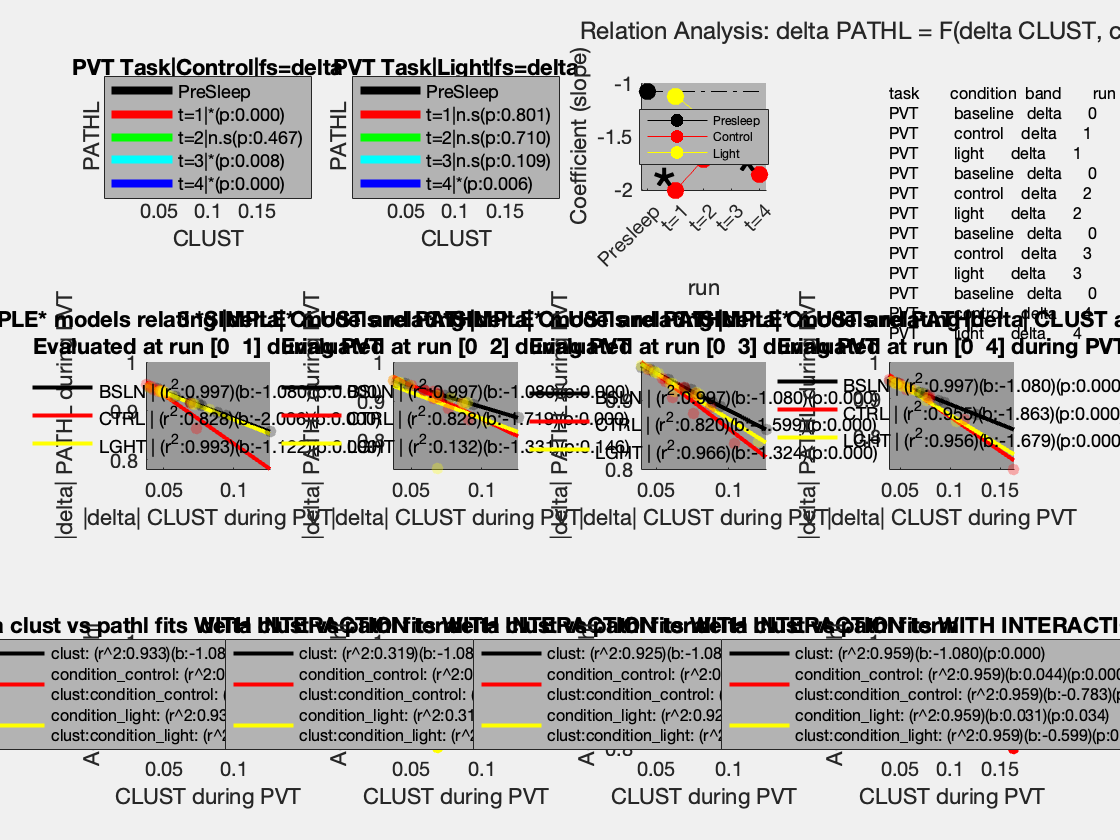

clearvars -except DF
close all force
clc;
IV = 'clust';
DV = 'pathl';
cogtask   = 'PVT';
band    = 'delta';


DF_b = plotslopetimecourse(DF,DV,IV, cogtask, band);

# FUNCTION: Combination Test

function [lm_smp, lm_int] = testslopemaster(DF, desired_cogtask,desired_band, desired_run, opts)
    arguments
        DF, desired_cogtask,
        desired_band
        desired_run 
        opts.display_info = false
        opts.runplots_simple = true
        opts.runplots_interaction = true;
        opts.runplots_rawpoints = false;        
    end

    desired_run_vs_bl = [0 desired_run];
    lm_smp = testslope(DF,  desired_cogtask, desired_band,desired_run_vs_bl,...
        'runplots',opts.runplots_simple);    
    
    lm_int = testinteraction(DF, desired_cogtask, desired_band,desired_run_vs_bl,...
        runplots_interaction = opts.runplots_interaction ,runplots_rawpoints = opts.runplots_rawpoints);

    if opts.display_info
        fprintf('%s %s', lm_smp.all_info,lm_int.all_info)
    end
end

# FUNCTION: Simple Model

function  [LM,df_grouped] = testslope(DF,desired_cogtask, desired_band,desired_runs,opts)
    arguments
        DF, desired_cogtask, desired_band,desired_runs,
        opts.desired_DV = 'pathl'
        opts.desired_IV = 'clust';
        opts.display_info =  false;
        opts.runplots = false;
        opts.runplots_ax = [];
    end
    df_grouped = dfmastersplit(DF,  desired_cogtask, {'baseline','control','light'},desired_band,desired_runs,'keepchannels', false,'suppresswarning',true);    

    % === get data frames
    [df_bl, df_cntl, df_light] = splitgroupeddf(df_grouped);


    % Presleep
    lm_bl   = fitlm(df_bl,'ResponseVar',opts.desired_DV,'PredictorVars',opts.desired_IV);   
    lm_bl_info =sprintf('BSLN | %s', getlminfo(lm_bl, opts.desired_IV)); 

    % Control   
    lm_cntl = fitlm(df_cntl,'ResponseVar',opts.desired_DV,'PredictorVars',opts.desired_IV);     
    lm_cntl_info =sprintf('CTRL | %s',getlminfo(lm_cntl,opts.desired_IV));

    % Light
    lm_light    = fitlm(df_light,'ResponseVar',opts.desired_DV,'PredictorVars',opts.desired_IV);    
    lm_light_info =sprintf('LGHT | %s', getlminfo(lm_light,opts.desired_IV));

    % Plot if desired
    linewidth = 2;
    if opts.runplots    
        if isempty(opts.runplots_ax)
            opts.runplots_ax = nexttile;
        end
        axes(opts.runplots_ax)
        opts.runplots_ax.NextPlot = 'add';  
        opts.runplots_ax.Color = [.6 .6 .6];

        % plot fit of when wake, both conditions
        runplot_confint = false;
        if runplot_confint
            ax_plot_bl = lm_bsl.plot(opts.runplots_ax);
            set(ax_plot_bl, 'Color', 'k');
            ax_plot_cntl = lm_cntl.plot(opts.runplots_ax);
            set(ax_plot_cntl, 'Color', 'r');
            ax_plot_light = lm_light.plot(opts.runplots_ax);
            set(ax_plot_light, 'Color', 'y');
            
            % Create Legend 
            legend(opts.runplots_ax,{'',lm_bl_info,'','','',lm_cntl_info,'','','',lm_light_info},'Location','best','Color',[.8 .8 .8],'Box','off');

        else
            [mn, mx] = bounds(df_grouped.(opts.desired_IV));  
            xbounds = [mn mx];
            line(opts.runplots_ax, xbounds, feval(lm_bl,xbounds),'Color', 'k','LineWidth', linewidth);
            line(opts.runplots_ax, xbounds, feval(lm_cntl,xbounds),'Color', 'r','LineWidth', linewidth);            
            line(opts.runplots_ax, xbounds, feval(lm_light,xbounds),'Color', 'y','LineWidth', linewidth);
            
            scatter(opts.runplots_ax, df_bl,'clust','pathl','filled','MarkerFaceColor','k','MarkerFaceAlpha',.3);
            scatter(opts.runplots_ax, df_cntl,'clust','pathl','filled','MarkerFaceColor','r','MarkerFaceAlpha',.3);
            scatter(opts.runplots_ax, df_light,'clust','pathl','filled','MarkerFaceColor','y','MarkerFaceAlpha',.3);

            legend(opts.runplots_ax,{lm_bl_info,lm_cntl_info,lm_light_info},'Location','best','Color',[.8 .8 .8],'Box','off');
            
        end
        
        

    
        
        band_name_str = sprintf('|%s|',lm_bl.VariableInfo.Range{ismember(lm_bl.VariableInfo.Row, 'band_ord')});        
        title_str = sprintf('3 *SIMPLE* models relating %s %s and %s\nEvaluated at run [%s] during %s',...
            band_name_str,...
            upper(opts.desired_IV), upper(opts.desired_DV),...
            num2str(desired_runs),...
            upper(desired_cogtask));

        ylabel(opts.runplots_ax,sprintf('%s %s',band_name_str, upper(opts.desired_DV)));
        xlabel(opts.runplots_ax,sprintf('%s %s',band_name_str, upper(opts.desired_IV)));
        title(opts.runplots_ax,title_str);  


    
        xlabel_str = sprintf('%s %s during %s\n', band_name_str, upper(opts.desired_IV), upper(desired_cogtask));
        ylabel_str = sprintf('%s %s during %s\n', band_name_str, upper(opts.desired_DV), upper(desired_cogtask));        
        xlabel(opts.runplots_ax,xlabel_str);
        ylabel(opts.runplots_ax,ylabel_str)
    end

    % Get information about linear models
    LM.baseline = lm_bl;
    LM.baseline_info = lm_bl_info;
    LM.control = lm_cntl;
    LM.control_info = lm_cntl_info;
    
    LM.light = lm_light;
    LM.light_info = lm_light_info;    
     
    LM.all_info = sprintf('SLOPE @ TIME=[%s] \n\t%s \n\t%s \n\t%s\n',num2str(desired_runs), LM.baseline_info,LM.control_info,LM.light_info);
    
    if opts.display_info 
        fprintf(LM.all_info)
    end
end

# FUNCTION: Interaction Model 

function  [lm_int, df_grouped] = testinteraction(DF,  desired_cogtask, desired_band,desired_runs, opts)
    arguments
        DF,  desired_cogtask, desired_band,desired_runs
        opts.desired_DV = 'pathl'
        opts.desired_IV = 'clust'
        opts.display_info=false
        opts.runplots_interaction = true;
        opts.runplots_interaction_ax = [];
        opts.runplots_slice = false;
    end
   
    % Get the data frame
     keepnodedata = false; % *** Modify later for other variables
    df_grouped = dfmastersplit(DF,  desired_cogtask, {'baseline','control','light'},desired_band,desired_runs,'keepchannels', keepnodedata,'suppresswarning',true);    
    

    % run a model with an interaction term
    lm = fitlm(df_grouped,"interactions",... 
        'ResponseVar',opts.desired_DV,...    
        'PredictorVars',{opts.desired_IV,'condition'},... 
        'CategoricalVars',{'condition'});   

    % save model information
    lm_int.lm = lm;
    lm_int.lm_varsinmodel = lm.VariableInfo(:,'InModel'); 

    lm_bl_coef = sprintf('%s: %s', opts.desired_IV,  getlminfo(lm , opts.desired_IV));

    coefname_x1x2 = @(condition) sprintf('condition_%s',condition);
    coefname_x3x4 = @(condition) sprintf('%s:condition_%s',opts.desired_IV ,condition);

    lm_cntl_int_1_info = sprintf('%s: %s',  coefname_x1x2('control'), getlminfo(lm , coefname_x1x2('control')));
    lm_cntl_int_2_info = sprintf('%s: %s',  coefname_x3x4('control'), getlminfo(lm , coefname_x3x4('control')));
    

    lm_light_int_1_info = sprintf('%s: %s',  coefname_x1x2('light'), getlminfo(lm , coefname_x1x2('light')));
    lm_light_int_2_info = sprintf('%s: %s',  coefname_x3x4('light'), getlminfo(lm , coefname_x3x4('light')));



    lm_int.all_info = sprintf('SLOPE DIFFERENCE @ TIME = %s\n \t-%s\n\n\t-%s\n\t-%s\n\n\t-%s\n\t-%s',...
        num2str(desired_runs),...
        lm_bl_coef,...
        lm_cntl_int_1_info,lm_cntl_int_2_info,...
        lm_light_int_1_info, lm_light_int_2_info)   ;

    % Warning about model
    warnstr_avetime = strcat('HEY LUIS!!!:You ran an interaction model that ignores the time variable...',...
        sprintf('%s\n',lm.Formula),...
        'Thus runs are being "averaged accross". See the output structure for more info');
    warning(warnstr_avetime);


    % Plot the interaction effects
    if opts.runplots_interaction  
        if isempty(opts.runplots_interaction_ax)
            opts.runplots_interaction_ax = nexttile;
        end

        axis(opts.runplots_interaction_ax);
        opts.runplots_interaction_ax.NextPlot = 'add';
        opts.runplots_interaction_ax.Color = [.7 .7 .7];

        
        axes(opts.runplots_interaction_ax)
        plt = plotInteraction(lm, 'condition', opts.desired_IV,'predictions');
        
        plt(1).Parent = opts.runplots_interaction_ax;
        plt(2).Parent = opts.runplots_interaction_ax;
        plt(3).Parent = opts.runplots_interaction_ax;
        plt(ismember({plt.DisplayName}, 'baseline')).Color = 'k';
        plt(ismember({plt.DisplayName}, 'control')).Color = 'r';
        plt(ismember({plt.DisplayName}, 'light')).Color = 'y';
        
        % Draw Scatters
        blidx   = lm.Variables.condition == 'baseline';
        cntl_idx = lm.Variables.condition == 'control';
        light_idx = lm.Variables.condition == 'light';
    
        x = lm.Variables.(opts.desired_IV);
        y = lm.Variables.(opts.desired_DV);
        scatter(opts.runplots_interaction_ax, x(blidx), y(blidx),'filled', 'MarkerFaceColor','k');
        scatter(opts.runplots_interaction_ax,x(cntl_idx), y(cntl_idx),'filled','MarkerFaceColor','r');
        scatter(opts.runplots_interaction_ax,x(light_idx), y(light_idx),'filled','MarkerFaceColor','y');    
               
        % Results
        bl_results_str = sprintf('%s\n',lm_bl_coef);        
        cntl_results_str = sprintf('%s \n%s\n',lm_cntl_int_1_info,lm_cntl_int_2_info);
        light_results_str = sprintf('%s \n%s',lm_light_int_1_info,lm_light_int_2_info);
        legend(opts.runplots_interaction_ax,{'',bl_results_str,cntl_results_str,light_results_str},'Interpreter','none','Location','best','FontSize',8);

        % Label
        xlabel(opts.runplots_interaction_ax,sprintf('%s during %s', upper(opts.desired_IV), desired_cogtask));
        title(opts.runplots_interaction_ax,sprintf('%s %s vs %s fits WITH INTERACTION term', desired_band, opts.desired_IV, opts.desired_DV));
    end

    if opts.runplots_slice
        plotSlice(lm);
    end



    
    if opts.display_info
        
        disp(lm_int.all_info )
    end

     
end


# FUNCTION: plot slopes accross time

function DF_b = plotslopetimecourse(DF, DV,IV,cogtask,bandname)
    arguments
        DF
        DV,IV
        cogtask
        bandname
    end
    % Init Figures;
    F = figure('Visible','on');
    FT = tiledlayout(F, 3,4);

    ax_idx_runs = [5 9;6 10;7 11; 8 12];

   
    % RUN MODELS
    DF_b = table;
    lm_simp_set = cell(1,4);
    lm_int_set = cell(1,4);    



    for t = 1:4
        ax_simple = nexttile(FT,ax_idx_runs(t,1));
        ax_inter = nexttile(FT,ax_idx_runs(t,2));        

        [df_b,lm_simp_set{t},lm_int_set{t}] = makecoeftable(DF,DV,IV,cogtask,bandname,t,...
            'runplots_simple',true,'runplots_simple_ax', ax_simple,...
            'runplots_int',true,'runplots_int_ax', ax_inter);
        DF_b = cat(1,DF_b,df_b); 
    end
        clear lm_int lm_simp

    
    % Iniate Plots 
    getxbounds = @(t) lm_int_set{t}.lm.VariableInfo.Range { ismember(lm_int_set{t}.lm.VariableInfo.Row, IV)};
    [xmin, xmax] = bounds([getxbounds(1) getxbounds(2) getxbounds(3) getxbounds(4)]);    
    xbounds = [xmin, xmax];


    % # # # # # # # # # # # # # # # # # # # # # # # # # # # # # # # # 
    % FIRST PLOT THE ACTUAL SLOPES LINES FOR EACH CONDITION ACCROSS TIME
    ax_cntl = nexttile(FT,1);
    ax_cntl.NextPlot = "add";
    ax_light = nexttile(FT,2);
    ax_light.NextPlot = "add";
    
    colorset = {'r', 'g', 'c', 'b'};
    linewidth = 4;


    for t = 1:4
        lm_simp = lm_simp_set {t};
        lm_int = lm_int_set {t};
        if t == 1
            lm =  lm_simp.baseline;
            line(ax_cntl, xbounds, feval(lm,xbounds),'Color', 'k', 'LineWidth', linewidth);
            issig_cntl = {'PreSleep'};
        
            line(ax_light, xbounds, feval(lm,xbounds),'Color', 'k','LineWidth', linewidth);
            issig_light = {'PreSleep'};
        end           
        lm =  lm_simp.control;
        issig_cntl = cat(2,issig_cntl, sprintf('t=%d|%s',t,getlminfo(lm_int.lm, 'clust:condition_control', statname = 'issig')));          
        line(ax_cntl, xbounds, feval(lm,xbounds),'Color', colorset{t},'LineWidth', linewidth)    ;        
        
        lm =  lm_simp.light;        
        issig_light = cat(2,issig_light, sprintf('t=%d|%s',t,getlminfo(lm_int.lm, 'clust:condition_light', statname = 'issig'))); 
        line(ax_light, xbounds, feval(lm,xbounds),'Color', colorset{t},'LineWidth', linewidth)    ;      
    end
    
    % Finaluze
    [ymin, ymax] = bounds([ax_light.YLim ax_cntl.YLim]);
    set(ax_light, 'Ylim',[ymin ymax], 'Xlim', xbounds,'Color', [.7 .7 .7]);
    xlabel(ax_light,upper(IV));
    ylabel(ax_light,upper(DV));

    set(ax_cntl, 'Ylim',[ymin ymax],'Xlim', xbounds, 'Color',[.7 .7 .7]);
    xlabel(ax_cntl,upper(IV));
    ylabel(ax_cntl,upper(DV));    
    
    writetitle = @(condition) sprintf('%s Task|%s|fs=%s', cogtask, condition, bandname);    
    title(ax_light,  writetitle('Light'))    
    title(ax_cntl,  writetitle('Control'))    
    
     % Add Legend
    legend(ax_light, issig_light,'Location','best');
    legend(ax_cntl, issig_cntl,'Location','best');
    
    % # # # # # # # # # # # # # # # # # # # # # # # # # # # # # # # #     
    % NOW PLOT THE COEFFICNETS OF THE SLOPES 
    
    ax_coef = nexttile(FT,3);
    ax_coef.NextPlot = 'add';
    ax_coef.Color = [.7 .7 .7];
    axes(ax_coef);
    box off
    getdf_b     = @(task,condition,band) DF_b(DF_b.task == task & ismember(DF_b.condition,condition) & DF_b.band == band,:);
    df_b        = getdf_b(cogtask,{'baseline','control','light'},bandname);
    bl_df_b     = getdf_b(cogtask,'baseline',bandname);
    cntl_df_b   = getdf_b(cogtask,'control',bandname);
    light_df_b  = getdf_b(cogtask,'light',bandname);

    plot(ax_coef,bl_df_b,'run','coef_smp', 'Color','k','MarkerSize', 30,'Marker','.');
    line(ax_coef, [0 4],bl_df_b.coef_smp *[1 1], 'Color','k','LineStyle','-.');
    plot(ax_coef, cntl_df_b,'run','coef_smp', 'Color','r','Marker','.','MarkerSize', 30);
    plot(ax_coef, light_df_b,'run','coef_smp', 'Color','y','Marker','.','MarkerSize', 30);

    % Draw a star for slopes that deviate from BL slope

    issig_rows = df_b.pval_dBL<.05;
    text(ax_coef, DF_b.run(issig_rows),DF_b.coef_smp(issig_rows),'*',...
        'FontSize',32,'HorizontalAlignment','right', 'VerticalAlignment','middle');
    
    % finalize figure
    set(ax_coef,'Color',[.7 .7 .7],'XTick',[0 1:4],'XTickLabel',{'Presleep','t=1','t=2','t=3','t=4'},'XLim',[-.25 4.25]);
    ylabel(ax_coef, 'Coefficient (slope)');
    legend(ax_coef, {'Presleep','', '', '','','Control','Light'},'FontSize',6,'Location','best')    


    % Display the full table
    ax_tbl = nexttile(FT,4);
    axes(ax_coef);    
    axis(ax_tbl,'off');
    tableCell = [DF_b.Properties.VariableNames; table2cell(DF_b)]; 
    tableCell(cellfun(@isnumeric,tableCell)) = cellfun(@num2str, tableCell(cellfun(@isnumeric,tableCell)),'UniformOutput',false); 
    tableCell(cellfun(@iscategorical,tableCell))    = cellfun(@(c) CatStr(c), tableCell(cellfun(@iscategorical,tableCell)),'UniformOutput',false)  ;          
    tableChar = splitapply(@strjoin,pad(tableCell),[1:size(tableCell,1)]');
    text(ax_tbl,0,1,tableChar,'VerticalAlignment','Top','HorizontalAlignment','Left','Interpreter','none','Units','normalized','FontSize',8);
    
    % Title
    title(FT,sprintf('Relation Analysis: %s %s = F(%s %s, condition, runs) during %s',bandname,upper(DV),bandname,upper(IV),upper(cogtask)),...
        'FontSize',12,'HorizontalAlignment','left','VerticalAlignment','bottom')
    

end

# FUNCTION TO MAKE TABLE OF COEFFICIENTS

function [DF_b,lm_simp,lm_int] = makecoeftable(DF,DV,IV,cogtask,band,run,opts)
    arguments
        DF,DV,IV,cogtask,band,
        run (1,1)
        opts.displaytable = false;
        opts.runplots_simple = false;
        opts.runplots_simple_ax = [];
        opts.runplots_int = false;
        opts.runplots_int_ax = [];
    end


    lm_simp = testslope(DF,  cogtask, band,[0 run], 'desired_IV',IV,'desired_DV',DV,...
        'display_info',false,'runplots',opts.runplots_simple,'runplots_ax',opts.runplots_simple_ax);    

    lm_int = testinteraction(DF, cogtask, band,[0 run],'desired_IV',IV,'desired_DV',DV,...
        'runplots_interaction',opts.runplots_int,'runplots_interaction_ax',opts.runplots_int_ax);


    % Create Table
    coef_bl = getcondcoeffs(lm_simp,lm_int,cogtask, 'baseline',band,0);
    coef_ctrl = getcondcoeffs(lm_simp,lm_int,cogtask, 'control',band,run);
    coef_light = getcondcoeffs(lm_simp,lm_int,cogtask, 'light',band,run);
           
    % Finalize
    DF_b = cat(1,coef_bl, coef_ctrl, coef_light);
    DF_b.condition  = categorical(DF_b.condition);
    DF_b.task  = categorical(DF_b.task);
    DF_b.band = categorical(DF_b.band);
    DF_b = dfrmcats(DF_b);

    if opts.displaytable
        disp(DF_b);
    end
    
    function coef_df = getcondcoeffs(lm_simp,lm_int,cogtask,  condname,band,run)
        tagvarnames = @(cond_lm_df,tag) strcat(cond_lm_df.Properties.VariableNames,tag);        

        % get from simple model
        [~, lmsmp_info]        = getlminfo(lm_simp.(condname), 'clust'); 
        lm_smp_df         = struct2table(lmsmp_info);
        lm_smp_df.Properties.VariableNames  = tagvarnames(lm_smp_df,'_smp'); 
        
        % from interaction model
        if strcmp('baseline',condname)
            lm_int_df = table(nan,'VariableNames',{'pval_dBL'});
            lm_int_cond_df = table(nan ,nan,'VariableNames',{'coef_int','pval_int'});
        elseif strcmp('control',condname) || strcmp('light',condname)
            [~, lmint_info]    = getlminfo(lm_int.lm, strcat('clust:condition_',condname)) ; 
            lm_int_df = table(lmint_info.pval,'VariableNames',{'pval_dBL'});
            
            [~, lmint_cond_info]    = getlminfo(lm_int.lm, strcat('condition_',condname)) ; 
            lm_int_cond_df = table(lmint_cond_info.coef, lmint_cond_info.pval,'VariableNames',{'coef_int','pval_int'});
            
        else 
            error('!!!HEY LUIS!!!, you can only specify "control" "baseline" or "light", spelled exactly as is')
        end

        % Create information table 
        info_df = table({cogtask}, {condname},{band},run,'VariableNames',{'task','condition','band','run'});
        coef_df = cat(2,info_df,lm_smp_df,lm_int_df,lm_int_cond_df);
    end
 


end

# FUNCTION: get lm info ===

function [lminfo_str, lminfo_vals]= getlminfo(lm, coeffname, opts)
    arguments
        lm
        coeffname
        opts.statname = 'all';
    end

    % validate
    if~ismember(coeffname,lm.CoefficientNames)
        error('!!!LUIS!!! You are asking for coefficients that do not exist in the model you ran...\n%s',lm.Formula);
    end

    coeff_val = lm.Coefficients.Estimate(ismember(lm.Coefficients.Row, coeffname));
    coeff_pval = lm.Coefficients.pValue(ismember(lm.Coefficients.Row, coeffname));

    rsqr_val = lm.Rsquared.Adjusted;

    lminfo_vals.coef = coeff_val;
    lminfo_vals.pval = coeff_pval;     
    lminfo_vals.rsqr = rsqr_val;
    switch opts.statname 
        case 'all'
        lminfo_str = sprintf('(r^2:%.03f)(b:%.03f)(p:%.03f)',rsqr_val, coeff_val, coeff_pval);   
        case 'issig'
            if coeff_pval < .05
                lminfo_str = sprintf('*(p:%.03f)',coeff_pval);
            else
                lminfo_str = sprintf('n.s(p:%.03f)',coeff_pval);                
            end
            

    end
end

# FUNCTION: Split and make data frame for each condition

function [df_bl, df_cntl, df_light] = splitgroupeddf(df_grouped)
    arguments
        df_grouped
    end

    if not(ismember({'baseline','control','light'},unique(df_grouped.condition)))
        error('LUIS!!!: your data frame needs to contain data for all three conditions')
    end
    % Presleep
    df_bl   = df_grouped(df_grouped.condition == 'baseline',:);

    % Control
    df_cntl = df_grouped(df_grouped.condition == {'control'},:);

    % Light
    df_light    = df_grouped(df_grouped.condition == {'light'},:);   



end

# Modify SOME Data Frames

function df_grouped_new = modifydf(df_sort)
    vars2compare = {'pathl','clust','band_ord','condition','sbj','betw','gpsd','run'};
    srtdf = @(df) sortrows(df(:,vars2compare),{'pathl','clust'});
    df_sort = srtdf(df_sort);

    comppathl   = @(df1,df2) all(ismember(df1,df2));

    % check if its the first model
    df_cmp_0 = load("outlierdf_PVT_delta_t1.mat");
    df_cmp_0 = srtdf(df_cmp_0.df_grouped);
    if height(df_cmp_0) == height(df_sort)
        if comppathl(df_cmp_0,df_sort)
            warnstr = strcat('\nHEY LUIS: you noticed that this data frame (containing samples during PVT) has extreme pathlength value in the control condition\n',...
                'The interactoin model you are running includes this value. You you need to modify the code to remove it\n',...
                'Note however that even after removing this data point, the interaction model that tests difference in slopes between presleep and control are still significant\n',...
                'however, visually, it is not apperant that the slopes and the data points are indeed different when you remove the value');
            warning(sprintf(warnstr));
        end
    end      

    % check if its the second model same as first but with run 2 addedd
    df_cmp_1 = load("outlierdf_PVT_delta_t1t2.mat");
    df_cmp_1 = srtdf(df_cmp_1.df_grouped);
    if height(df_cmp_1) == height(df_sort)
        if comppathl(df_cmp_1,df_sort)
            df_sort(1,:) = []; % uncomment to remove outlier
            warnstr = strcat('\nHEY LUIS: you noticed that this data frame (containing samples during PVT) has extreme pathlength value in the light during run 2\n',...
                'This sample was removed\n',...
                'interestngly, by remving this outlier the slope changes during control are exaggerated, showing a more robust effect');
            warning(sprintf(warnstr));
        end
    end

    % check if its the 3rd model
    df_cmp_2 = load("outlierdf_GoNogo_delta_t1.mat");
    df_cmp_2 = srtdf(df_cmp_2.df_grouped);
    if height(df_cmp_2) == height(df_sort)
        if comppathl(df_cmp_2,df_sort)
            df_sort(1:2,:) = []; 
            warnstr = strcat('\nyou noticed that this data frame (containing samples during GONOGO) has 2 extreme pathlength values under control during run 2\n',...
                'These two samples were removed from the data\n', 'even after removal there still does not exist a significant interaction');

            warning(sprintf(warnstr));
        end
    end

    % check if its the 4rd model  (same as third but with run 2 added)
    df_cmp_3 = load("outlierdf_GoNogo_delta_t1t2.mat");
    df_cmp_3 = srtdf(df_cmp_3.df_grouped);
    if height(df_cmp_3) == height(df_sort)
        if comppathl(df_cmp_3,df_sort)
            df_sort(1:2,:) = []; 
            warnstr = strcat('\nyou noticed that this data frame (containing samples during GONOGO) has 2 extreme pathlength values under control during run 2\n',...
                'These two samples were removed from the data\n', 'even after removal there still does not exist a significant interaction');
            warning(sprintf(warnstr));
        end
    end


    df_grouped_new = df_sort;

end


RESULTS SUMMAT

background

awards

awards

how i got to arl

worked for steve

went to grad school,

# Time course of the slope

still just need to build a read me file about this

SUMMARY

So it seems that during the PV task, in both the delta and beta bands the slope deviates from baseline after waking, but only in the control conditions. The slope under blue light is always the same as the slope during presleep. 

During the go nogo task, the slope in the delta band deviates from the baseline slope under BOTH the control and blue light conditions. In the beta band, the slopes never deviate from the presleep slope, neither under control or blue light. That is, sleep inertia with or without blue light has no impact on the slope in the beta band.

The slope of the delta band during the Math has an 'opposite' behavior during the PVT task:  the slope only changes under the blue light, rather than the control condition. the beta band during the math task has some mixed effects: under the control condition, the slope never deviates from presleep slope, but there are two time points under blue light where the slope changes

In all cases where the value of the slope changes -sleep, these changes tend to occur at a time AFTER t = 1. Im not sure what this means, since one  would expect the effects of sleep inertia to be strongest at t = 1.

# Detailed Summary: Slope changes during PV Task in beta and delta band under control conditions

**Delta Band**

Under control, the slope frequently changes from the pre-sleep slope

(1) note that during control the slope is always significant at all time points. Importantly this is true immediately after waking at t=1, when the effects of sleep inertia should be at their highest.

(2) during control, the slope is significantly different from the pre-sleep slope at all time points except for the second. That is, the slope is steeper during three of the 4 time points after waking

 Under the blue light condition, the slope is for the most part the same as the pre-sleep slope

(1) note that during blue light the slope is always significant at all time points

(2) except for t = 4, the slope under blue light is similar to the slope during pre-sleep. That is, the slope is similar during 3 of the four time points after waking with blue light.

Comments

Most importantly, the changes in slopes occur at t=1 (when the effects of sleep inertia should be at their ) only in the control condition during the PV task. there are no changes under blue light

**Beta Band**

Slope tends to deviate during the control condition

Under the control condition, the slope is always significant

During control condition, the slope becomes steeper 2 out of the 4 time points (@ t=2 and t =3)

Under the Blue Light condition the slope never changes from presleep condition

the slope is always significant

the slope never changes at any time point after pre-sleep

Comments

Most importantly, the changes in slopes occur at t=1 (when the effects of sleep inertia should be at their ) only in the control condition during the PV task. there are no changes under blue light

**General Comments**

in general the slope tends to change from presleep after abrupt awakening under control conditions. This is most obvious in the delta band, which shows a change at  t = 1, where as the beta band deviates at other times and less than the slope of the beta band. Furthermore, the slope under blue light is almost always the same as the pre-sleep slope.

# Detailed Summary: During GoNogo task, slopes changes in DELTA band occur under both blue light and control at a delayed time after waking

**DELTA BAND**

Slopes are always significant in both conditions

During control AND during light, the slope is always significant at all time points 

    - this is the same thig we saw during the PV Task

Slopes become steeper at delayed time points (t=3, and 4) under both control and blue light conditions

this differs from PVT delta band in two ways

- the change in slope occurs at a delayed time point

- slopes change under BOTH blue light and control conditions

**BETA BAND**

Slopes are always significant in both conditions

this is the same in all tasks and bands i have assessed at this point

however there is a monpr exceptopm at t=4 in the control condition, but its almost significant (p=.08)

Slopes never deviate from the presleep slope, neither under blue light, or in control

tfirst time ive seen this 'complete lack' of an effect in neither condition.

# Detailed Summary: During the Math task Slope changes in DELTA band resemble those during the GoNogo task

**DELTA BAND**

Slopes are always significant in both conditions

Note that theres a minor exception at t=1 under the control condition, but the p-value is almost significant

again this is consistent accross tasks

The slopes change at t=2,3 and 4 under under the blue light condition only

this is  similar to what we see during the GONOGO task in the delta band under blue light, except here the slope change occurs at a slightly eralier time point at t = 2

however, this largely contrasts the effects observed during the PVT task in which the changes occured in the control situation

and also differs from the GoNogo task that had dual effects under both conditions

**BETA BAND**

Slopes are always significant in both conditions

again this is consistent accross tasks

The slopes change at t=2,3 and 4 under under the blue light condition only (same exact effects as the delta band)

this differs from the Gonogo because in gonogo beta band  there are never changes in the light, however it is similar because gonogo because there are no changes in the control condition.

again during PVT most of the changes occur under the control condition, unlike we see here